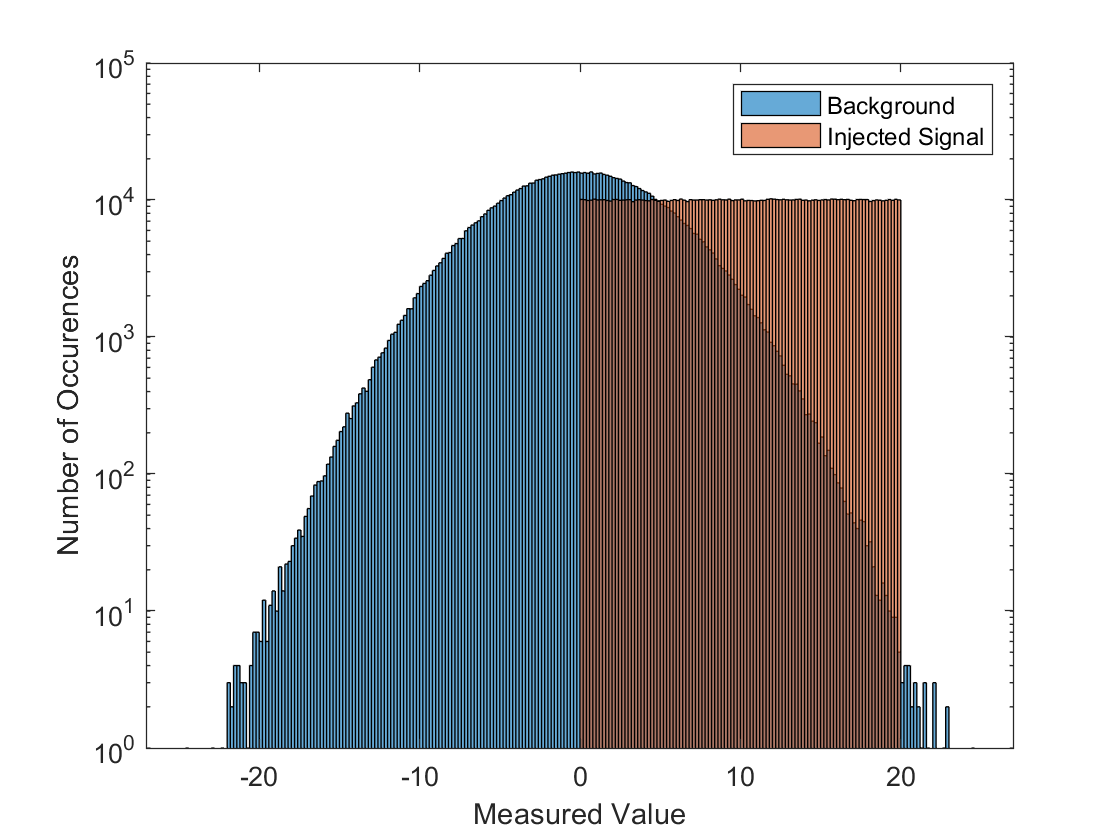

clear, close all, clc

bkgd = normrnd(0, 5, 1,1000000);
set(gca,'YScale','log')

histogram(bkgd)

sig = 20*rand(1,1000000);
hold on
histogram(sig)
set(gca,'YScale','log')
legend('Background', 'Injected Signal')
xlabel('Measured Value')
ylabel('Number of Occurences')

data = bkgd + sig;
hold off

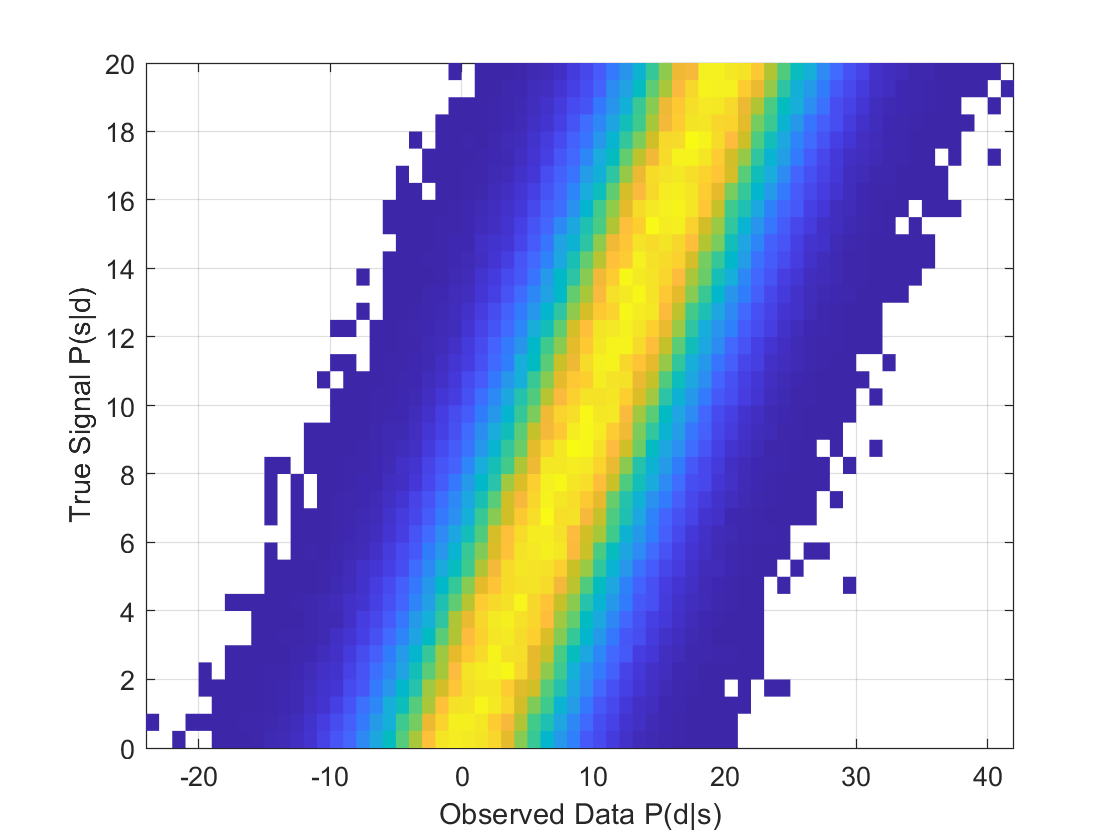


histogram2(data,sig,'DisplayStyle', 'tile');
xlabel('Observed Data P(d|s)')
ylabel('True Signal P(s|d)')

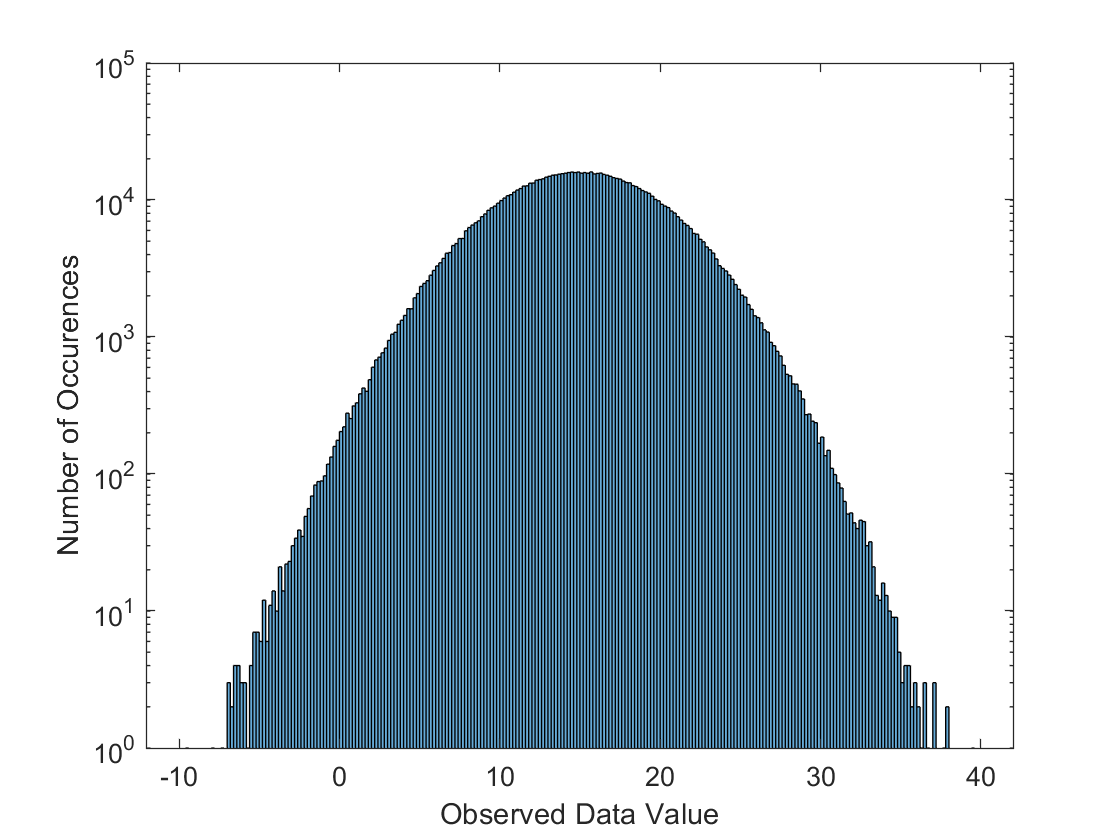


histogram(bkgd + 15)
set(gca,'YScale','log')
xlabel('Observed Data Value')
ylabel('Number of Occurences')

Essentially this plot is selecting a true signal value from the y-axis on the 2D Histogram and then plotting the corresponding horizontal slice. 

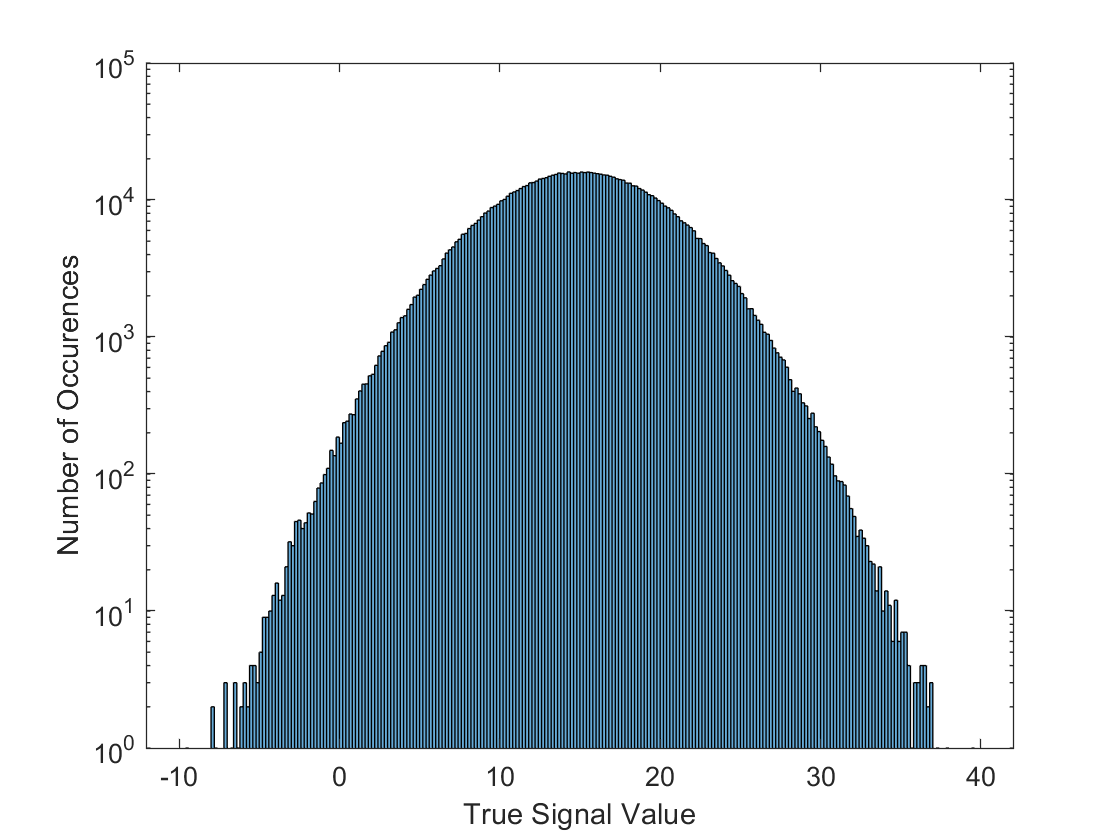

histogram(15-bkgd)
set(gca,'YScale','log')
xlabel('True Signal Value')
ylabel('Number of Occurences')

hold off


Essentially this plot is selecting a observed data value from the x-axis on the 2D Histogram and then plotting the corresponding vertical slice. 

## Problem 2

bkgd = normrnd(7, 5, 1,1000000);
set(gca,'YScale','log')

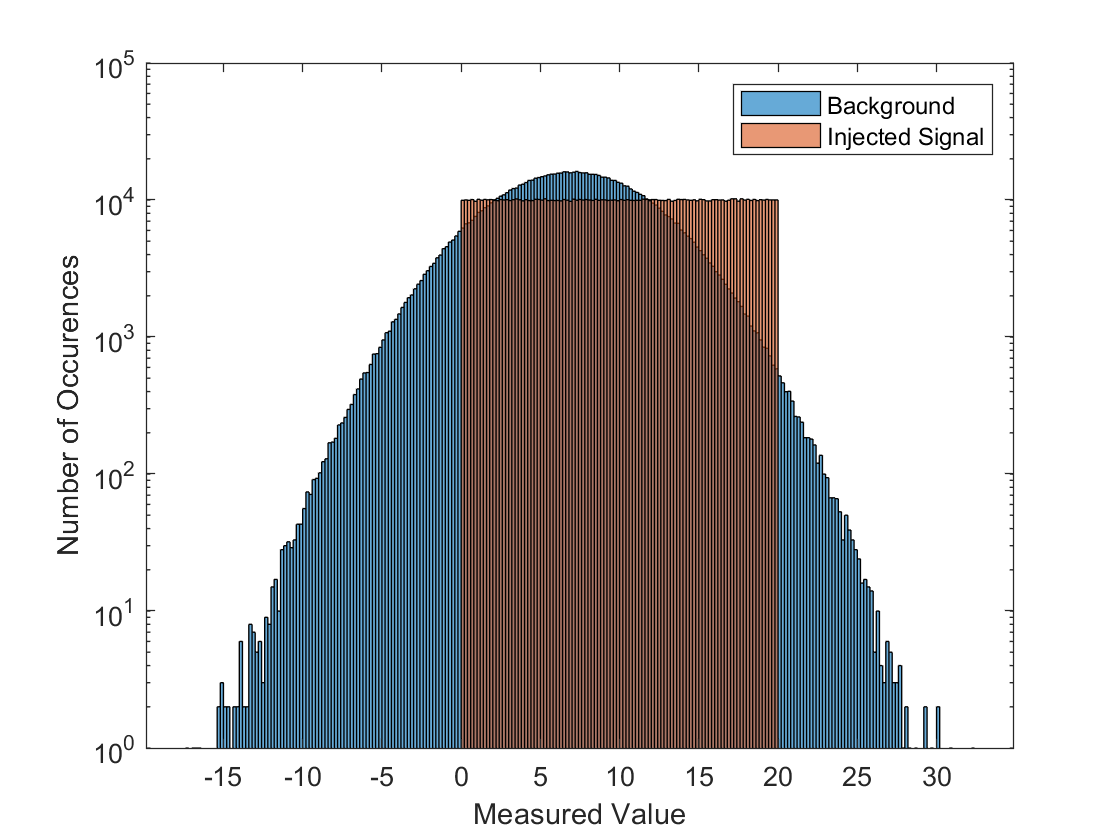


histogram(bkgd)

sig = 20*rand(1,1000000);
hold on
histogram(sig)
set(gca,'YScale','log')
legend('Background', 'Injected Signal')
xlabel('Measured Value')
ylabel('Number of Occurences')

data = bkgd + sig;
hold off

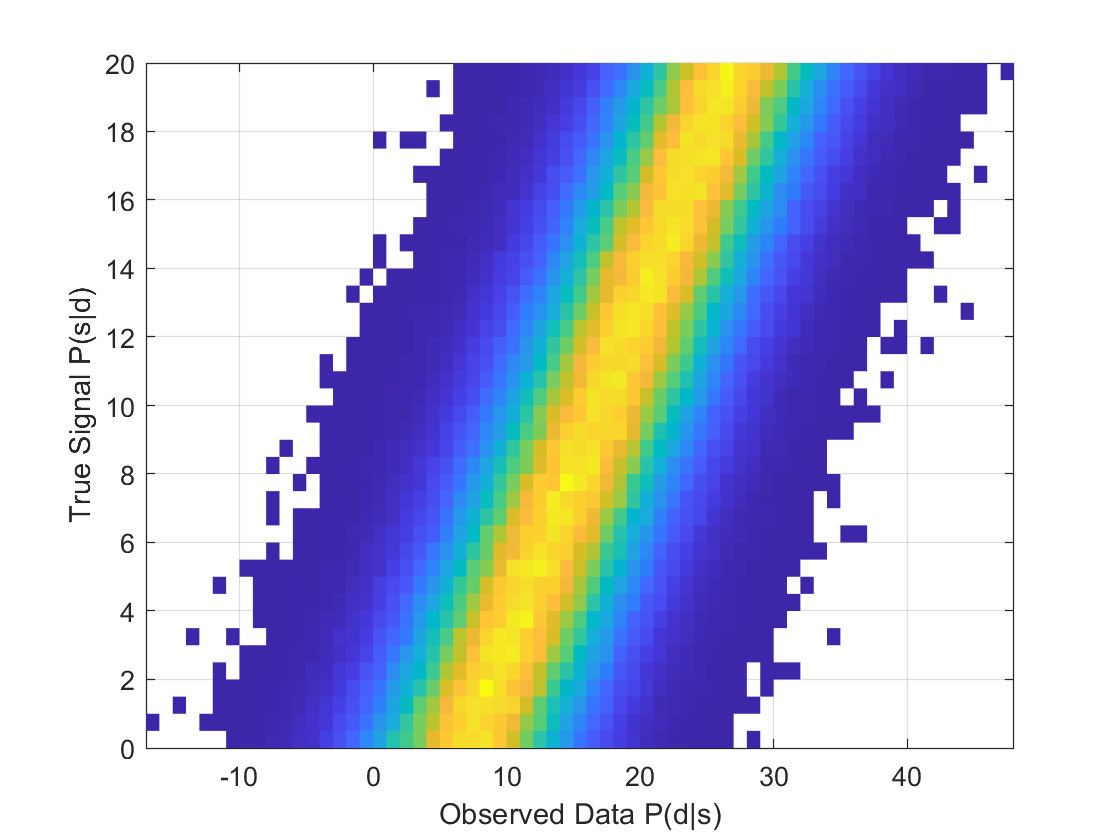


histogram2(data,sig,'DisplayStyle', 'tile');
xlabel('Observed Data P(d|s)')
ylabel('True Signal P(s|d)')

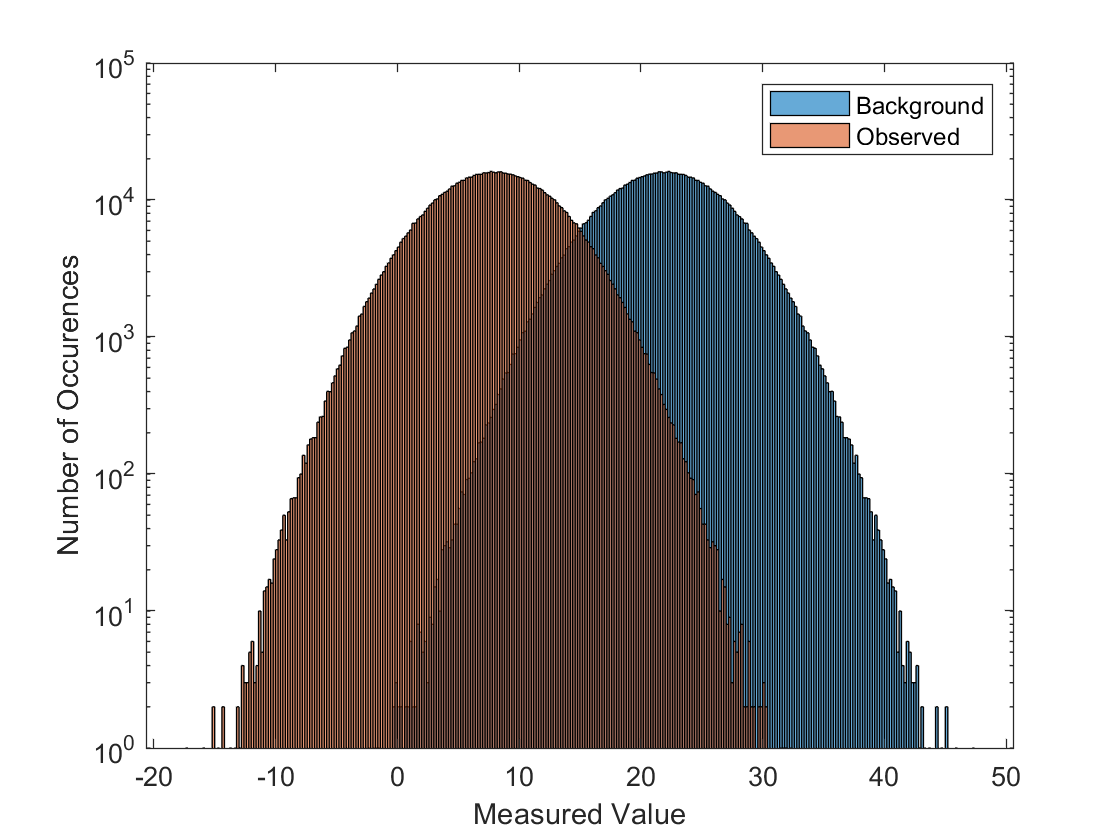


histogram(bkgd + 15)
set(gca,'YScale','log')
xlabel('Measured Value')
ylabel('Number of Occurences')

hold on
histogram(15-bkgd)
set(gca,'YScale','log')
legend('Background', 'Observed')

The two plots aren't centered on the same mean because sincew the background distribution is no longer centered at 0. When the background is shifted up but 15 to create the horizontal slice and vertical slice is created by taking 15 - background. They no longer reside on the same mean value. 

With a zero mean


$$0 + 15 = 15
$$



$$15 - 0 = 15$$


but with a non zero mean


$$15 + 7 = 22$$



$$15-7 = 8$$
